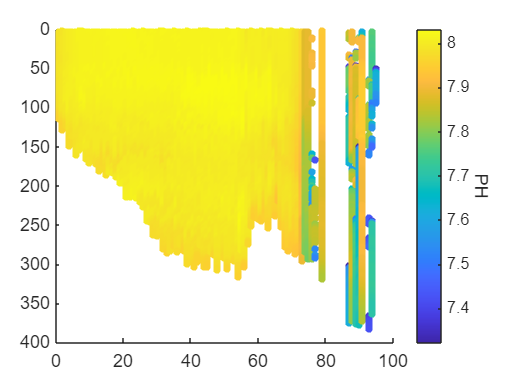

fn = 'C:\Users\lgrady\Documents\MATLAB\ARGO_PROCESSING\MFILES\LG_WIP\RTQC\CSIO_data\2902884_Sprof.nc';
INFO= ncinfo(fn);
Vars = INFO.Variables.Name;

PH = ncread(fn,'PH_IN_SITU_TOTAL');
PHqf = ncread(fn,'PH_IN_SITU_TOTAL_QC');
% DEAL WITH QC FLAGS (char arrays to num & space to NaN)
PHqf_1d = sscanf(regexprep(PHqf(:)',' ','7'),'%1f'); 
PHqf_1d(PHqf_1d==7) = NaN;
sz = size(PH);
PHqf = reshape(PHqf_1d,sz(1),sz(2));
badPH = PHqf==4;
% goodPH = PH(~badPH);
PH(badPH) = NaN;

N = ncread(fn, 'NITRATE');
Nqf = ncread(fn, 'NITRATE_QC');
Nqf_1d = sscanf(regexprep(Nqf(:)',' ','7'),'%1f'); 
Nqf_1d(Nqf_1d==7) = NaN;
sz = size(N);
Nqf = reshape(Nqf_1d,sz(1),sz(2));
badN = Nqf==4;
N(badN) = NaN;

PRES = ncread(fn,'PRES');
goodPH_PRES = PRES;
goodPH_PRES = PRES(~badPH);
goodN_PRES = PRES;
goodN_PRES = PRES(~badN);

%Convert cycle into 2d matrix with dimensions of PH and N
CYC = ncread(fn,'CYCLE_NUMBER');
CYC_mat = repmat(CYC',length(N),1);
goodPH_CYC = CYC_mat(~badPH);
goodN_CYC = CYC_mat(~badN);

figure;
scatter(CYC_mat(:),PRES(:),16,PH(:),"filled")
set(gca, 'YDir','reverse');
col = colorbar;
col.Label.String = 'PH';
col.Label.FontSize = 10;
col.Label.Rotation = -90;

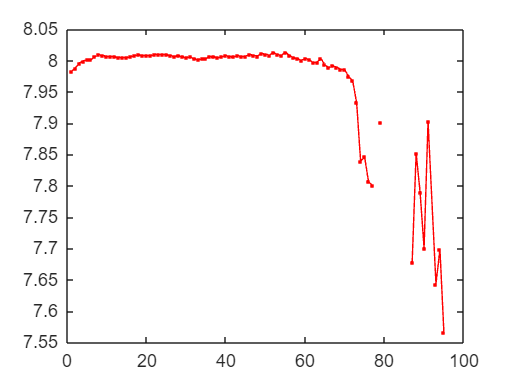


figure;
plot(CYC, mean(PH,1,'omitmissing'), '.-r')

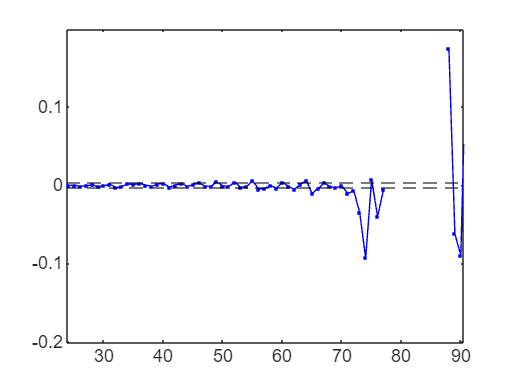


meanPH = mean(PH,1,'omitmissing');
phDrift = [0 diff(meanPH)];
MNphDrift = mean(phDrift(1:70),'omitmissing');
STDphDrift = std(phDrift(1:70),'omitmissing');

figure;
plot(CYC, phDrift, '.-b');
yline(MNphDrift+STDphDrift,'--k');
yline(MNphDrift-STDphDrift,'--k');

% INPUTS
% DATA: A data structure in the same format as floatViz files (can be a subset of the data)

% varType: inputs to the EsperMix function to output a desired variable
% 3 = PH
% 5 = NITRATE

% qcDepth: A lower and upper bound of depths that the deep tests will be applied to
% I.E. qcDepth = [1480 1520]

% badO2Test: A logical indicating whether the O2 sensor has been placed on the BSL
% 0 = O2 is NOT on the BSL
% 1 = O2 is on the BSL (ESPER with no O2 will be used)

% omitBadDeepData: A logical indicating whether the subset of deep data includes
% data flagged as bad (8) or omits it/
% 0 = Bad data is NOT omitted and will be included in the deep tests
% 1 = (default) Bad is omitted and will not be included in the deep tests

%Identify the subsampled deep data from DATA depending on the desired varType

%NITRATE TEST THRESHOLDS
rtqcDATA.N_sensorDriftThd = 1; %Cycle-to-cycle delta for NITRATE
rtqcDATA.N_rangeChkThd = [-10 55]; %Range check test
rtqcDATA.N_consecCounter = 3; %Number of consecutive test breaches before flagging

%PH TEST THRESHODLS
rtqcDATA.PH_sensorDriftThd = .01; %Cycle-to-cycle delta for PH
rtqcDATA.PH_rangeChkThd = [7.3 8.5];
rtqcDATA.PH_consecCounter = 3;

if omitBadDeepData
    %Subset deep data within "qcDepth" range that is also flagged as good or questionable
    deepDATA = dat(dat(:,iZ)>=qcDepth(1) & dat(:,iZ)<=qcDepth(2) & dat(:,iVar+1)~=8,:);
else
    deepDATA = dat(dat(:,iZ)>=qcDepth(1) & dat(:,iZ)<=qcDepth(2),:);
end

%CHECK FOR GPS ISSUES AND CALCULATE ESPERMIX
%===========================================================================================
%GPS is a necessary variable to estimate ESPERMIX, so if a float is missing a GPS fix for a cycle
%than it is returned as a NaN. The stations without gps are kept track of to display in the final message.

%List of stns WITHOUT a gps fix (also generates a the output data structure "rtqcDATA")
rtqcDATA.noGPSstns = unique(dat(isnan(dat(:,iLon))|isnan(dat(:,iLat)),iStn));

%CHECK FOR ANY MISSING OXYGEN
%===========================================================================================
%O2 is not required to estimate EsperMix, but does change the equation. This block locates any cycles
%that are missing O2 at the qc depth. If any cycles are missing O2 at the then EsperMix is calculated 
%without O2. This is done to keep consistent with how MBARI qc's floats.

%Identify missing O2 stations

%Retreive station data
stnDATA = deepDATA(:,iStn);

%Create array of unique stations in deep PH dataset
rtqcDATA.stns = unique(deepDATA(:,iStn))';

%Create empty logical array to populate with test results
noO2logical = logical.empty(length(rtqcDATA.stns),0);

%Loop through all stations
for i = 1:length(rtqcDATA.stns)

    %Test if any oxygen is missing from each station and store the test result in the logical array
    noO2logical(i) = isnan(mean(deepDATA(stnDATA==rtqcDATA.stns(i),iO), "omitmissing"));
end

%Retrieve any stations that are missing O2
rtqcDATA.noO2stns = stnDATA(noO2logical);

%Apply a blanket test to the entire float
%If there are missing O2 stations, then it's possible this float is qc'd using ESPER (no O2)
missingO2Test = ~isempty(rtqcDATA.noO2stns);
%===========================================================================================

%REALTIME QC TESTING
%===========================================================================================
%The heart of this function is the realtime qc tests. This block runs the data through the cycle delta
%and reference anomaly tests. Using logical indices of the cycles that breach the qc thresholds (in the
%beginning of the code), a third test is run to find any sequences of 3 or more consecutive cycles that 
%breach the thresholds. This ensures that natural noise during 1 or 2 cycles doesn't trigger a warning.

%Create blank array for mean deep data at each station
rtqcDATA.deepDATA_mean = NaN(length(rtqcDATA.stns),1);

%Range check for data throughout the entire profile
rtqcDATA.rangeChkBreach = logical.empty(length(rtqcDATA.stns),0);

for i = 1:length(rtqcDATA.stns)
    
    %Assign indices for the current station
    stnIDX_deep = deepDATA(:,iStn)==rtqcDATA.stns(i);
    stnInd_prof = dat(:,iStn)==rtqcDATA.stns(i);
    
    %Deep data at the current station in the loop
    deepData_atStn = deepDATA(stnIDX_deep,iVar);
    
    %Entire profile at the current station in the loop
    profData_atStn = dat(stnInd_prof,iVar);
    
    %Mean of float data at depth for the current cycle
    rtqcDATA.deepDATA_mean(i,1) = mean(deepData_atStn,'omitmissing');

    %Perform a range check test over the entire profile
    rtqcDATA.rangeChkBreach(i,1) = any(profData_atStn<=rtqcDATA.PH_rangeChkThd(1) | profData_atStn>=rtqcDATA.PH_rangeChkThd(2));
end

rtqcDATA.rangeChkTriggerStns = rtqcDATA.stns(rtqcDATA.rangeChkBreach);

%Append phDelta with a 0 at the beginning to compensate for indices offset
rtqcDATA.cycleDelta = [0; diff(rtqcDATA.deepDATA_mean)];

%RUN CONSECUTIVE TRIGGER TESTS
%Code based on example found from:
%https://www.mathworks.com/matlabcentral/answers/366126-how-many-consecutive-ones

%FOR GROSS SENSOR DRIFT (CYCLE DELTA)
%===========================================================================================

%Create logical arrays for delta and ref anom tests (any delta or refAnom beyond the 
%threshold is flagged)
cycleDeltaBreach = abs(rtqcDATA.cycleDelta) >= rtqcDATA.deltaThd; %& (abs(rtqcDATA.refAnom) >= refAnomThd);


%Create empty zero arrays to populate with indices later
deltaOut = zeros(size(cycleDeltaBreach'));

%Duplicate that zero array but prepend and append a zero for indexing
deltaOutB = [0,cycleDeltaBreach',0];

%Find the index of any INITIAL failure, where (i.e. any location where cycleDeltaBreach goes from 0 to 1)
iDelta = strfind(deltaOutB, [0 1]);

%Now find the index of any FINAL failure and subtract the INITIAL failure index to
%calculate how many consecutive points exist between the initial and final failure 
deltaOut(iDelta) = strfind(deltaOutB, [1 0]) - iDelta; %append the zeros array "delta/ref Out"

%i.e. If failures begin at cycle 3 and end at cycle 7, this means cycle 3,4,5,6,7 get flagged. By taking
%the difference between the initial (3) and final (7), we find that this test was triggered 5 
%consecutive times from cycle 3 (the initial cycle is counted)

%Filters out instances of 1 or 2 consecutive failures that could be natural noise in the environment
iDelta = iDelta(deltaOut(iDelta) >= rtqcDATA.consecCounter);

%Create an array of cycle blocks that consists of each INITIAL and FINAL failure
deltaStnBlocks = [rtqcDATA.stns(iDelta); rtqcDATA.stns(iDelta)+deltaOut(iDelta)-1]';

%Create empty arrays to be appended with all failed stations
rtqcDATA.cycleDeltaTriggerStns = [];

%For each pair of cycles, populate the previous empty array with ALL cycles between the INITIAL and FINAL failure cycles
deltaDim = size(deltaStnBlocks);

if deltaDim(1) == 1 & ~isempty(deltaStnBlocks)
       rtqcDATA.cycleDeltaTriggerStns = [rtqcDATA.cycleDeltaTriggerStns, deltaStnBlocks(1):1:deltaStnBlocks(2)];
elseif deltaDim(1) > 1
    for x = 1:deltaDim(1)
        rtqcDATA.cycleDeltaTriggerStns = [rtqcDATA.cycleDeltaTriggerStns, deltaStnBlocks(x,1):1:deltaStnBlocks(x,2)];
    end
end